# Coupled Attitude and Orbit Motion

## note

UKF推定のための真値をmatファイルに保存する吉村先生のコード．

## references 

## revisions

©2022  y.yoshimura, y.yoshimula@gmail.com, y.yoshimura.a64@m.kyushu-u.ac.jp

clc
clear

curdir = pwd;
addpath(genpath(strcat(curdir, '/../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得

## constants and satellite parameters

const = orbitConst; % for orbital motion
earthVSOP = vsopConst; % for earth orientation

% for time calculation
iau06 = readIAU06;
leapJD = leapS; % load database
fname = "EOP_20_C04_one_file_1962-now.txt";
eopDataAll = readEOP(fname);


model = 2;

if model == 1
    objName = 'flatPlate.obj';
    nCompo = 1; % # of object in .obj file
    sat = readSC(objName, nCompo); % satellite shape and optical parameters

    sat.J = diag([10, 15, 20]); % moment of inertia, kgm^2
    sat.m = 50; % mass, kg
    sat.nu = ones(size(sat.faces,1),1) .* 800; %とりあえずベタうち
    sat.nv = ones(size(sat.faces,1),1) .* 800;
    sat.F0 = ones(size(sat.faces,1),1) .* 0.5;
    sat.kappa = 0.0; % thermal emissivity
elseif model == 2
    objName = 'boxWing.obj';
    nCompo = 3; % # of object in .obj file
    sat = readSC(objName, nCompo); % satellite shape and optical parameters

    % sat.J = diag([45, 50, 60]); % moment of inertia, kgm^2
    sat.J = diag([55, 40, 65]);
    sat.m = 100; % mass, kg
    %   optical parameters at wing (manually...)
    % sat.Ca(193:end,:) = 0.1; % absorption
    % sat.Cd(193:end,:) = 0.6; % diffuse
    % sat.Cs(193:end,:) = 0.3; % specular
    sat.Ca = 0.1; % absorption
    sat.Cd = 0.6; % diffuse
    sat.Cs = 0.3; % specular
    sat.nu = ones(size(sat.faces,1),1) .* 800; %とりあえずベタうち
    sat.nv = ones(size(sat.faces,1),1) .* 800;
    sat.F0 = ones(size(sat.faces,1),1) .* 0.5;
    sat.kappa = 0.0; % thermal emissivity
else
    error('invalid model flag');
end

Reading Object file : boxWing.obj
  % Blender v2.83.1 OBJ File: 'boxWing.blend'
  %www.blender.org
Reading Material file : boxWing.mtl
  % Blender MTL File: 'boxWing.blend'
  % Material Count: 2
Finished Reading Material file
Finished Reading Object file


ans =    242     3


ans =    472     3


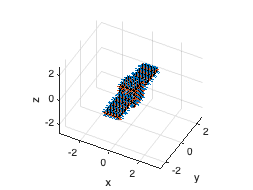

showSC(sat,"Normal","on") % visualize satellite

## initial condition

### attitude

% qIni = zyx2q(4, -1.3222, 1.4059, 0); % initial quaternion, q(4) is the scalar part
wIni = deg2rad([0.1, -0.0, -0.3]); % initial angular rate, rad/s for asymmetric body
qIni = [0, 0, 0, 1];
% qIni = zyx2q(4, -1.3222, 1.4059, 1.0);
% wIni = [0, 0, deg2rad(sqrt(0.1))];
% wIni = [0.0009, 0.0009, -0.0012];
% wIni = [-0.0012, 0.0012, 0.0000];

### orbit

tle.oe = $a {\rm [km]}, e,i {\rm [rad]},\Omega {\rm [rad]},\omega{\rm [rad]},M{\rm [rad]}$

tle = readTLE('JCSAT2.txt', const);

[rIni, vIni] = oe2rv(tle.oe, 1, const); % at inertial frame, km, km/s
rIni = rIni .* 10^3; % m
vIni = vIni .* 10^3; % m/s
jd = tle.jd; % Julian day, day
[yy, mm, dd, hh, m, s] = jd2gc(jd);
utc = datetime([yy, mm, dd, hh, m, s]); % UTC (datetime format)

% initial condition
xIni = [rIni, vIni, qIni, wIni];
% tspan = 0:5:60*60*6;

tstep = 1;
tspan = 0:tstep:60*10;
% tspan = 0:tstep:60*3;

## observer location

obsLon = deg2rad(130.216544); % longitude, rad
obsLat = deg2rad(33.594649); % latitude, rad
[obsPosECEF(1), obsPosECEF(2), obsPosECEF(3)] = sph2cart(obsLon, obsLat, const.RE); % observer position@ECEF, km
obsPosECEF = obsPosECEF .* 10^3; % 1x3 vec, m

dcmITRF2gcrf = itrf2gcrf(utc, leapJD, iau06, eopDataAll);
qITRF2gcrf = dcm2q(4, dcmITRF2gcrf);
qGCRF2itrf = dcm2q(4, dcmITRF2gcrf');
obsECI = qRotation(4, obsPosECEF, qITRF2gcrf); % observer @ECI, m, 1x3 vec.


## ODE

options = odeset('RelTol',1e-9,'AbsTol',1e-9);
[t_, x_] = ode89(@(t,x)eomAttiOrb(t,x,const,sat), tspan, xIni, options);

## data handling

jdHistory = tle.jd + s2day(t_); % time history in Julian day
[yy, mm, dd, hh, m, s] = jd2gc(jdHistory);
utc = datetime([yy, mm, dd, hh, m, s]); % UTC (datetime format)
for ii = 1:length(t_)
    dcmITRF2gcrf = itrf2gcrf(utc(ii), leapJD, iau06, eopDataAll);
    qITRF2gcrf(ii,:) = dcm2q(4, dcmITRF2gcrf);
end

r = x_(:,1:3); % m, position at i-frame
v = x_(:,4:6); % m/s, velocity at i-frame
q = x_(:,7:10); % quaternion w.r.t. inertial frame
w = x_(:,11:13); % rad/s, angular rate  w.r.t. inertial frame
tmp = q2zyx(4, q);
phi = tmp(:,1);
theta = tmp(:,2);
psi = tmp(:,3);

### Sun position and Observer positions

sunPosI = sun(jdHistory, const, earthVSOP);
sunPosI = sunPosI .* 10^3; % m
sunRel = sunPosI - r; % relative vec from sat to sun @inertial frame, nx3, m
sunPosB = qRotation(4, normRow(sunRel), q);% sun unit directional vectors @body-fixed frame, nx3

obsECI = qRotation(4, repmat(obsPosECEF,length(jdHistory),1), qITRF2gcrf); % observer position @ECI, nx3 m
obsRel = obsECI - r; % relative vec from sat to observer @inertial frame, nx3, m
obsB = qRotation(4, normRow(obsRel), q); % relative observer directional vectors@inertial frame, nx3,


### Light curve

nu = shadow(r./10^3, sunPosI./10^3, const.RS, const.RE); % calc Earth's shadow
[mApp, ~] = lc(sat, 4, q, r, obsECI, sunPosI, nu, 'AS'); % relative magnitude
fObs = magInv(mApp, vecnorm(obsRel,2,2));


## show figs

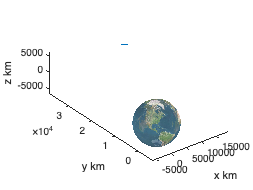

figure
plot3(r(:,1)./1000, r(:,2)./1000,r(:,3)./1000)
hold on
plot3(obsECI(:,1)./1000, obsECI(:,2)./1000,obsECI(:,3)./1000,'r')
tmp = gmst(jdHistory(end));
drawEarth(tmp, 0.6, const);
xlabel('x km'), ylabel('y km'), zlabel('z km')
axis equal

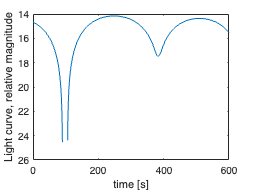


figure
plot(t_, mApp)
xlabel('time [s]'), ylabel('Light curve, relative magnitude')
set(gca, 'YDir', 'reverse')


%% attitude
figure % quaternion
tFig = tiledlayout(4,1), nexttile

tFig =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [4 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


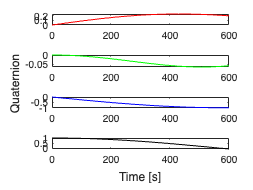

plot(t_,q(:,1),'r'), nexttile
plot(t_,q(:,2),'g'), nexttile
plot(t_,q(:,3),'b'), nexttile
plot(t_,q(:,4),'k')
xlabel(tFig, 'Time [s]')
ylabel(tFig, 'Quaternion ')

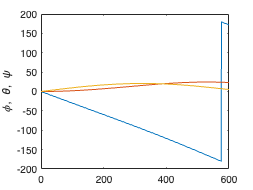


figure % attitude angle
plot(t_, rad2deg(phi))
hold on
plot(t_, rad2deg(theta))
plot(t_, rad2deg(psi))
ylabel('\phi, \theta, \psi')

%
% figure % angular rate,
% plot(t_, rad2deg(w(:,1)))
% hold on
% plot(t_, rad2deg(w(:,2)))
% plot(t_, rad2deg(w(:,3)))
% ylabel('angular rate deg/s')

h = normRow(obsB(1,:) +sunPosB(1,:))

h =     0.2719   -0.9598   -0.0701


## save (all) variables

fName = objName(1:end-4); % exclude '.obj'

save(strcat(fName,'.mat'), 't_','mApp','q','phi','theta','psi',...
    'w','r','v','obsECI','jdHistory', 'sat','obsRel','sunPosI')